%%
clear all
R = 0.05 

R = 0.0500

t = linspace(0,10,200)'

t =          0
    0.0503
    0.1005
    0.1508
    0.2010
    0.2513
    0.3015
    0.3518
    0.4020
    0.4523


r = R*[t,t.*t] 

r =          0         0
    0.0025    0.0001
    0.0050    0.0005
    0.0075    0.0011
    0.0101    0.0020
    0.0126    0.0032
    0.0151    0.0045
    0.0176    0.0062
    0.0201    0.0081
    0.0226    0.0102


x = r(:,1)

x =          0
    0.0025
    0.0050
    0.0075
    0.0101
    0.0126
    0.0151
    0.0176
    0.0201
    0.0226


y = r(:,2)

y =          0
    0.0001
    0.0005
    0.0011
    0.0020
    0.0032
    0.0045
    0.0062
    0.0081
    0.0102


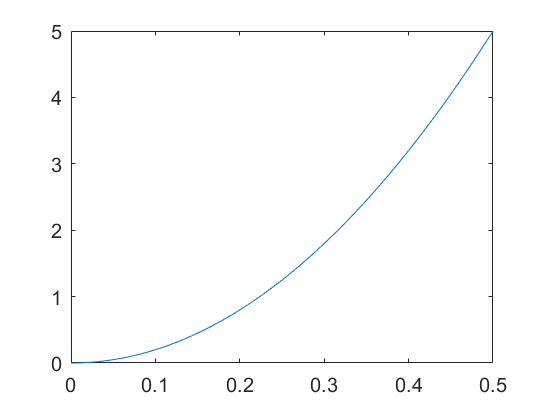

plot(x,y) % plot the points in 2D

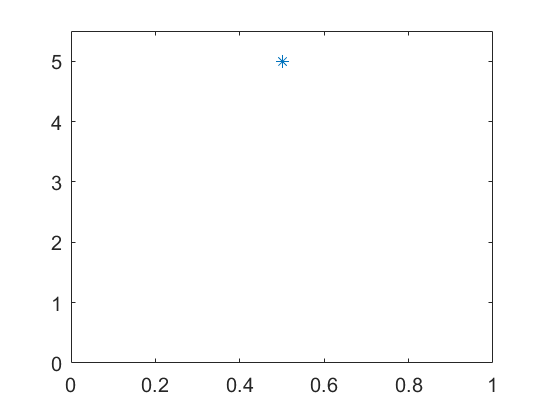

for i = 1:length(x)
plot(x(i),y(i),'*') % animate the plotting instead
axis([0 1 0 5.5])
drawnow
end

%%
clear % clear the workspace
R = 0.05% define the parameter R

R = 0.0500

t = linspace(0,10,1000)' % lay down a set of points in the u-domain as a column vector

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0501
    0.0601
    0.0701
    0.0801
    0.0901


r = R*[t,t.*t] % compute the position vector

r =          0         0
    0.0005    0.0000
    0.0010    0.0000
    0.0015    0.0000
    0.0020    0.0001
    0.0025    0.0001
    0.0030    0.0002
    0.0035    0.0002
    0.0040    0.0003
    0.0045    0.0004


drdu = diff(r)./diff(t) % compute an approximation to the derivative

drdu =     0.0500    0.0005
    0.0500    0.0015
    0.0500    0.0025
    0.0500    0.0035
    0.0500    0.0045
    0.0500    0.0055
    0.0500    0.0065
    0.0500    0.0075
    0.0500    0.0085
    0.0500    0.0095


That = drdu./sqrt(sum(drdu.^2,2)) % compute the unit tangent vector

That =     0.9999    0.0100
    0.9995    0.0300
    0.9987    0.0500
    0.9976    0.0699
    0.9960    0.0897
    0.9940    0.1094
    0.9916    0.1290
    0.9889    0.1485
    0.9858    0.1678
    0.9824    0.1868


N = diff(That)./diff(t(1:end-1)) % compute the normal vector

N =    -0.0400    1.9987
   -0.0799    1.9951
   -0.1195    1.9891
   -0.1586    1.9808
   -0.1972    1.9702
   -0.2351    1.9574
   -0.2722    1.9424
   -0.3083    1.9254
   -0.3435    1.9063
   -0.3774    1.8854


Nhat = N./sqrt(sum(diff(drdu).^2,2)) % make it a unit normal

Nhat = 1.0e+03 *

   -0.0400    1.9967
   -0.0798    1.9931
   -0.1193    1.9871
   -0.1584    1.9788
   -0.1970    1.9682
   -0.2349    1.9554
   -0.2719    1.9405
   -0.3080    1.9234
   -0.3431    1.9044
   -0.3771    1.8836


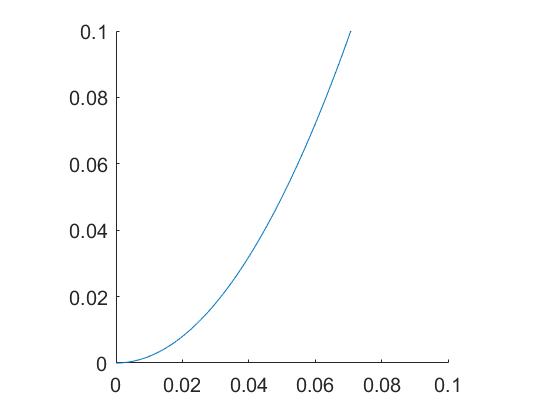

for i = 1:length(t)-2 % animate the unit tangent vector and unit normal vector
    clf
    hold on
    plot(r(:,1),r(:,2)) % plot the entire path
    quiver(r(i,1),r(i,2),That(i,1),That(i,2)) % plot That
    quiver(r(i,1),r(i,2),Nhat(i,1),Nhat(i,2)) % plot Nhat
    axis equal % equal axis so that it looks like a circle
    axis([0 0.1 0 0.1]) % plot domain large enough to see what is going on
    drawnow % force the plotting otherwise it will plot everything at once
end